clear all

#  EXTRAER ARCHIVOS

NxyzTABLE = readtable('Nxyz.xlsx','ReadRowNames',true);

NxyzTABLE.Properties.VariableNames{1} = 'X';
NxyzTABLE.Properties.VariableNames{2} = 'Y';
NxyzTABLE.Properties.VariableNames{3} = 'Z';


num_col = length(NxyzTABLE.Properties.RowNames);


%       CREAMOS TABLAS CON DATOS
xyz = NxyzTABLE{1:num_col,{'X','Y','Z'}}; %tabla con xyz
x_o = NxyzTABLE{1:num_col,{'X'}}; %separamos datos para graficar puntos
y_o = NxyzTABLE{1:num_col,{'Y'}};
z_o = NxyzTABLE{1:num_col,{'Z'}};


# DATOS PISTA

logitudPista=3020;
anchuraPista=30;
%   DATOS SUPERFICIE DE TRANSICION
FranjaAnchura=150;
FranjaLongitud=60;
pendienteTransicion=0.143;
altura=45;
%  DATOS DESPEGUE
LogitudBordeInteriorDespegue=180;
DivergenciaDespegue=0.125;
logitudTotal=1500;
pendienteDespegue=0.02;
%   DATOS APROX
LogitudBordeInteriorAprox=300;
DivergenciaAprox=0.15;
LongitudPrimeraSeccion=3000;
pendienteAproximacion=0.02;


## Creamos figura pista

XXpista = [0,0,0,0,logitudPista,logitudPista,logitudPista,logitudPista]';
YYpista = [anchuraPista/2,anchuraPista/2,-anchuraPista/2,-anchuraPista/2,anchuraPista/2,anchuraPista/2,-anchuraPista/2,-anchuraPista/2]';
ZZpista = [0,1,0,1,0,1,0,1]';
Figurapista = alphaShape(XXpista,YYpista,ZZpista); %cramos la figura


## CREAMOS SUPERFICIE DE TRANSICION

% estas son las aristas de nuestro volumen
 XXtrans = [-FranjaLongitud,-FranjaLongitud,logitudPista+FranjaLongitud,logitudPista+FranjaLongitud,...
    -(altura/pendienteTransicion+FranjaLongitud),-(altura/pendienteTransicion+FranjaLongitud),-FranjaLongitud,...
    -FranjaLongitud,logitudPista+FranjaLongitud,logitudPista+FranjaLongitud,logitudPista+FranjaLongitud+altura/pendienteTransicion,...
    logitudPista+FranjaLongitud+altura/pendienteTransicion]';
YYtrans = [FranjaAnchura,-FranjaAnchura,-FranjaAnchura,+FranjaAnchura,...
    FranjaAnchura+DivergenciaAprox*(altura/pendienteTransicion),-(FranjaAnchura+DivergenciaAprox*(altura/pendienteTransicion)),...
    altura/pendienteTransicion+FranjaAnchura,-(altura/pendienteTransicion+FranjaAnchura),...
    altura/pendienteTransicion+FranjaAnchura,-(altura/pendienteTransicion+FranjaAnchura),...
    FranjaAnchura+DivergenciaAprox*(altura/pendienteTransicion),...
    -(FranjaAnchura+DivergenciaAprox*(altura/pendienteTransicion))]';
ZZtrans = [0,0,0,0,altura,altura,altura,altura,altura,altura,altura,altura]';

Figuratrans = alphaShape(XXtrans,YYtrans,ZZtrans); %cramos la figura

%TRANS 2
XXtrans2 = [-FranjaLongitud,-FranjaLongitud,logitudPista+FranjaLongitud,logitudPista+FranjaLongitud,...
    -FranjaLongitud,-FranjaLongitud,logitudPista+FranjaLongitud,logitudPista+FranjaLongitud]';
YYtrans2 = [FranjaAnchura,-FranjaAnchura,-FranjaAnchura,+FranjaAnchura,...
    altura/pendienteTransicion+FranjaAnchura,-(altura/pendienteTransicion+FranjaAnchura),...
    altura/pendienteTransicion+FranjaAnchura,-(altura/pendienteTransicion+FranjaAnchura)]';
ZZtrans2 = [0,0,0,0,altura,altura,altura,altura]';

Figuratrans2 = alphaShape(XXtrans2,YYtrans2,ZZtrans2);

%TRANS 3 
XXtrans3 = [-FranjaLongitud,-FranjaLongitud,...
    -(altura/pendienteTransicion+FranjaLongitud),-(altura/pendienteTransicion+FranjaLongitud),...
    -(altura/pendienteTransicion+FranjaLongitud),-(altura/pendienteTransicion+FranjaLongitud),]';
YYtrans3 = [FranjaAnchura,-FranjaAnchura,...
    FranjaAnchura+DivergenciaAprox*(altura/pendienteTransicion),-(FranjaAnchura+DivergenciaAprox*(altura/pendienteTransicion)),...
    FranjaAnchura+DivergenciaAprox*(altura/pendienteTransicion),-(FranjaAnchura+DivergenciaAprox*(altura/pendienteTransicion))]';
ZZtrans3= [0,0,altura,altura,0,0]';

Figuratrans3 = alphaShape(XXtrans3,YYtrans3,ZZtrans3);

%TRANS 4
XXtrans4 = [logitudPista+FranjaLongitud,logitudPista+FranjaLongitud,...
    logitudPista+FranjaLongitud+altura/pendienteTransicion,logitudPista+FranjaLongitud+altura/pendienteTransicion...
    logitudPista+FranjaLongitud+altura/pendienteTransicion,logitudPista+FranjaLongitud+altura/pendienteTransicion]';
YYtrans4 = [FranjaAnchura,-FranjaAnchura,...
    FranjaAnchura+DivergenciaDespegue*(altura/pendienteTransicion),-(FranjaAnchura+DivergenciaDespegue*(altura/pendienteTransicion)),...
    FranjaAnchura+DivergenciaDespegue*(altura/pendienteTransicion),-(FranjaAnchura+DivergenciaDespegue*(altura/pendienteTransicion)),]';
ZZtrans4 = [0,0,altura,altura,0,0]';

Figuratrans4 = alphaShape(XXtrans4,YYtrans4,ZZtrans4);




#### MIRAR SI ESTA EN SUPERCICIE TRANS i TRANS 2, TRANS 3

EstaEnTRANS = inShape(Figuratrans,xyz); %mirar si es dentro o fuera (figura,puntos)
EstaEnTRANS2 = inShape(Figuratrans2,xyz);
EstaEnTRANS3 = inShape(Figuratrans3,xyz);
EstaEnTRANS4 = inShape(Figuratrans4,xyz);



## CREAMOS SUPERFICIE DE APROXIMACION

% estas son las aristas de nuestro volumen
XXaprox = [-(LongitudPrimeraSeccion+FranjaLongitud),-(LongitudPrimeraSeccion+FranjaLongitud),-FranjaLongitud,-FranjaLongitud,...
    -(LongitudPrimeraSeccion+FranjaLongitud),-(LongitudPrimeraSeccion+FranjaLongitud)]';
YYaprox = [FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion,-(FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion),...
    -FranjaAnchura,FranjaAnchura,FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion,...
    -(FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion)]';
ZZaprox = [0,0,0,0,pendienteAproximacion*LongitudPrimeraSeccion,pendienteAproximacion*LongitudPrimeraSeccion]';

FiguraAprox = alphaShape(XXaprox,YYaprox,ZZaprox); %cramos la figura


####  MIRAR SI ESTA EN SUPERCICIE APROXIMACION

EstaEnAPROX = inShape(FiguraAprox,xyz); %mirar si es dentro o fuera (figura,puntos)


## CREAMOS SUPERFICIE DE DESPEGUE

% estas son las aristas de nuestro volumen
XXdespegue = [logitudPista+FranjaLongitud,logitudPista+FranjaLongitud,logitudPista+FranjaLongitud+logitudTotal,...
    logitudPista+FranjaLongitud+logitudTotal,logitudPista+FranjaLongitud+logitudTotal,...
    logitudPista+FranjaLongitud+logitudTotal]';
YYdespegue = [FranjaAnchura,-FranjaAnchura,-(FranjaAnchura+DivergenciaDespegue*logitudTotal),...
    FranjaAnchura+DivergenciaDespegue*logitudTotal,-(FranjaAnchura+DivergenciaDespegue*logitudTotal),...
    FranjaAnchura+DivergenciaDespegue*logitudTotal]';
ZZdespegue = [0,0,0,0,pendienteDespegue*logitudTotal,pendienteDespegue*logitudTotal]';
FiguraDespegue = alphaShape(XXdespegue,YYdespegue,ZZdespegue); %cramos la figura

#### MIRAR SI ESTA EN SUPERCICIE DESPEGUE

EstaEnDESPEGUE = inShape(FiguraDespegue,xyz); %mirar si es dentro o fuera (figura,puntos)



#### CREAMOS SUPERFICIE DE CONO 

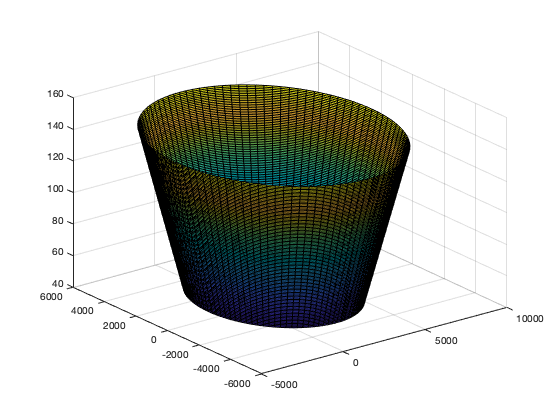

h =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [101×101 double]
           YData: [101×101 double]
           ZData: [101×101 double]
           CData: [101×101 double]

  Show all properties



% 
h = 0:1:100;
r = 20*h+4000; %radio va de 4000 a 6000
[x,y,z]=cylinder(r,100);
z= 100*z+45; % el 100* es para rescalarlo de 0 a 1 A  0 a 100, y els 45 para subir. 
x = x+logitudPista/2; % centramos en cono en pista
h = surf(x,y,z)


A = [h.XData(:),h.YData(:),h.ZData(:)];

h_alturas = 45:1:100;

for i = 1:1:length(h_alturas)
    last = length(A);
    A(last+1,3) = h_alturas(i);
end
 
FiguraCono = alphaShape(A(:,1), A(:,2),A(:,3));

#### MIRAR SI ESTA EN SUPERCICIE CONO


EstaEnCONO = inShape(FiguraCono,xyz)

EstaEnCONO = 5×1 logical array
   0
   0
   0
   0
   1


#    DATOS EN TABLA

InorOuttableTRANS = table(EstaEnTRANS); %converir logicos a tabla
tablaconTRANS = [NxyzTABLE InorOuttableTRANS]; %juntar tablas

InorOuttableTRANS2 = table(EstaEnTRANS2); %converir logicos a tabla
tablaconTRANS2 = [tablaconTRANS InorOuttableTRANS2]; %juntar tablas

InorOuttableTRANS3 = table(EstaEnTRANS3);
tablaconTRANS3 = [tablaconTRANS2, InorOuttableTRANS3];

InorOuttableTRANS4 = table(EstaEnTRANS4);
tablaconTRANS4 = [tablaconTRANS3, InorOuttableTRANS4];

InorOuttableAPROX = table(EstaEnAPROX); %converir logicos a tabla
tablaconTRANSiAPROX = [tablaconTRANS4 InorOuttableAPROX]; %juntar tablas

InorOuttableDESPEGUE = table(EstaEnDESPEGUE); %converir logicos a tabla
tablaconTRANSiAPROXiDESPEGUE = [tablaconTRANSiAPROX InorOuttableDESPEGUE]; %juntar tablas

InorOuttableCONO = table(EstaEnCONO); %converir logicos a tabla
tablaconTRANSiAPROXiDESPEGUECONO = [tablaconTRANSiAPROXiDESPEGUE InorOuttableCONO]; %juntar tablas


%       COMPARAMOS TABLA
c3= tablaconTRANSiAPROXiDESPEGUECONO{:,'EstaEnDESPEGUE'};
c2= tablaconTRANSiAPROXiDESPEGUECONO{:,'EstaEnAPROX'};
c1= tablaconTRANSiAPROXiDESPEGUECONO{:,'EstaEnTRANS'};
c4= tablaconTRANSiAPROXiDESPEGUECONO{:,'EstaEnTRANS2'};
c5= tablaconTRANSiAPROXiDESPEGUECONO{:,'EstaEnTRANS3'};
c6= tablaconTRANSiAPROXiDESPEGUECONO{:,'EstaEnTRANS4'};
c7= tablaconTRANSiAPROXiDESPEGUECONO{:,'EstaEnCONO'};

ESTADENTROALGUNAZONA= c1+c2+c3+c4+c5+c6+c7; % sumamos todos
InorOuttableRESULT = table(ESTADENTROALGUNAZONA); %converir logicos a tabla
tablaFINAL = [tablaconTRANSiAPROXiDESPEGUECONO InorOuttableRESULT]

tablaFINAL = 5×11 table
                      X       Y      Z     EstaEnTRANS    EstaEnTRANS2    EstaEnTRANS3    EstaEnTRANS4    EstaEnAPROX    EstaEnDESPEGUE    EstaEnCONO    ESTADENTROALGUNAZONA
                     ____    ____    __    ___________    ____________    ____________    ____________    ___________    ______________    __________    ____________________

    1 WDI               0    -170     2       false          false           false           false           false           false           false                0          
    2 WDI            2200    -170     2      

RESULTlogic = logical(ESTADENTROALGUNAZONA);


%for para pintar en fuincion si dentro o no
sz = size(RESULTlogic);
for ii = 1:sz
      if RESULTlogic(ii) == 0
          f = 'o';
          c = 'Color';
          m = [0, 0, 255] / 255;
      else
          f = 'x';
          c = 'Color';
          m = [255, 0, 0] / 255;
      end
      plot3(x_o(ii),y_o(ii),z_o(ii),f,c,m,'MarkerSize', 10, 'LineWidth', 3) %plot de puntos obstaculos
      hold on
  end

%   contador de obstaculos:
counter = 0;
for ii = 1:sz
    if RESULTlogic(ii) == 0
        counter = counter + 0;
    else
        counter= counter+1;
    end
end
X = ['Número de obstáculos que pinchan nuestras zonas: ', num2str(counter), '.'];
disp(X)

Número de obstáculos que pinchan nuestras zonas: 2.


# %       CREAMOS ARCHIVO CON LOS NUEVOS DATOS


%NxyzTABLE = readtable('Nxyz.xlsx','ReadRowNames',true);

filename = 'NxyzFINAL.xlsx';

if exist('NxyzFINAL.xlsx')
    
    delete("NxyzFINAL.xlsx");
    writetable(tablaFINAL,filename);
    
else
    writetable(tablaFINAL,filename);
    
end




# PLOTS de FIGURAS

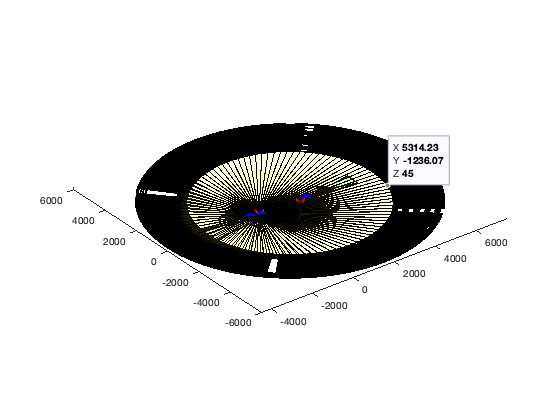



hold on %tener dos O MAS graficas en mismos ejes
plot(Figurapista,'FaceColor','black','FaceAlpha',1); %plot de pista

plot(Figuratrans,'FaceColor','red','FaceAlpha',0.1); %plot de trans
plot(Figuratrans2,'FaceColor','red','FaceAlpha',0.1); %plot de trans2
plot(Figuratrans3,'FaceColor','red','FaceAlpha',0.1); %plot de trans3
plot(Figuratrans4, 'FaceColor','red', 'FaceAlpha',0.1); %plot de trans4
% 
plot(FiguraAprox,'FaceColor','blue','FaceAlpha',0.1); %plot de aprox
% 
plot(FiguraDespegue,'FaceColor','green','FaceAlpha',0.1); %plot de despegue
plot(FiguraCono,'FaceColor','yellow','FaceAlpha',0.1);%plot de cono

hold off